# Recocido simulado

La idea es la siguiente:

=======================================================================

    Entrada $(f, T_0, a, L, T_f)$

    Genera una solución inicial y la asigna a la solución actual ($S_{act}$)

    Asigna la Temperatura inicial a la variable $T$

    while $T\geq Tf$

                   for un contador $j=1:L$ 

                        Generamos un "vecino" a la solución inicial y se asigna a ($S_{cand}$)

                        Se calcula $\delta = f(S_{cand}) - f(S_{act})$

                        Se genera un número aleatorio $X\sim\text{Uniforme}(0,1)$

                        if $x< \exp(-\delta / T)$ or $\delta<0$

                            
$$S_{act} = S_{cand}$$


                        endif

                    endfor

                    
$$T=aT_{act}$$


    endwhile    

## Egg crate function

Busquemos el mínimo de la función


$$f(x,y) = x^2 + y^2 + 25(\sin^2 x + \sin^2 y)$$


clear;

% Definimos la funcion
f = @(x,y) x.^2 + y.^2 + 25*((sin(x)).^2 + (sin(y)).^2);

% Matrices para visualizacion
[X,Y] = meshgrid(-5:0.01:5,-5:0.01:5);

% Guess inicial
rng('shuffle');
aa = -1;
bb = 1;
pd1 = makedist('Uniform',aa,bb);

% Distribucion para los vecinos
dx = 0.5;
pd2 = makedist('Uniform',-dx,dx);
% pd2 = makedist('Normal',0,dx);

% Solucion inicial
Sol_act = random(pd1,1,2);

% Temperatura
T0 = 0.5 * f(Sol_act(1), Sol_act(2));
T = T0;

% alpha
alph = 0.9;

% Ciclos dentro del while
L = 1000;

% Temperatura final
Tf = 1E-15;

% Contador
cc = 1;

% Visualizacion
clf;
hold off
surf(X,Y,f(X,Y))
view([-26.4 76.8])
% axis equal
alpha 0.75
shading interp
colormap hsv
hold on

while T>Tf
    for ii = 1:L
        
        % Generamos vecinos
        Sol_cand = Sol_act + random(pd2,1,2);
        
        delta = f(Sol_cand(1),Sol_cand(2)) - ...
                f(Sol_act(1),Sol_act(2));
        
        % Generamos una x aleatoria (volado) y comparamos con Boltzman
        x = rand;
        Pboltz = exp(-delta/T);
        
        if x<Pboltz || delta<0
            Sol_act = Sol_cand;
        end 
    end
    
    % Almacenamos el minimo en un vector
    Cmin(cc) = f(Sol_act(1), Sol_act(2));
    
    % Enfriamos
    T = alph*T;
    Temp(cc) = T;

    cc = cc+1;
    
    % Visualizacion
    scatter3(Sol_act(1), Sol_act(2), f(Sol_act(1), Sol_act(2)), 50 ,'.' ,'black'),
    hold on
    pause(0.01);
end

Sol_act

Sol_act =    -0.0002   -0.0016


f(Sol_act(1),Sol_act(2))

ans = 7.0889e-05

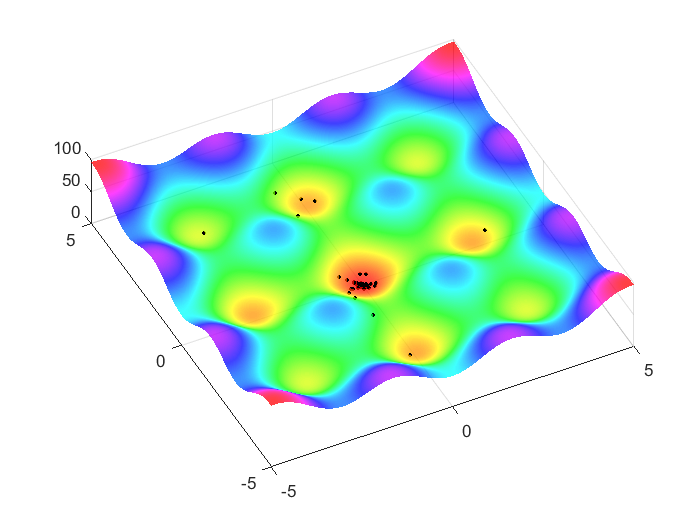

hold off

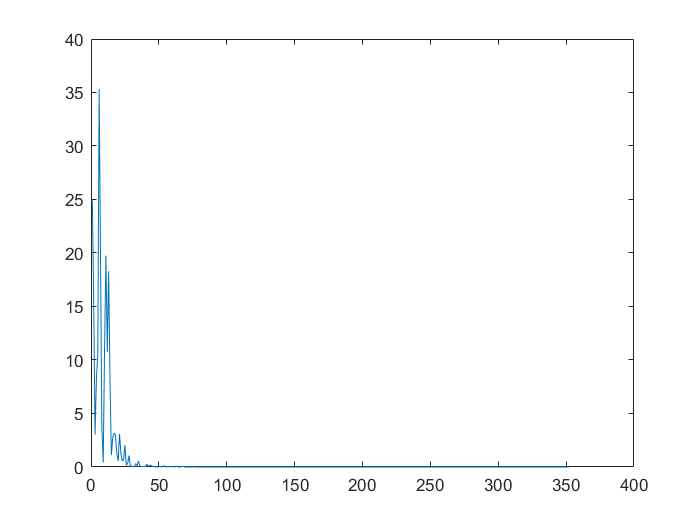

plot(Cmin)

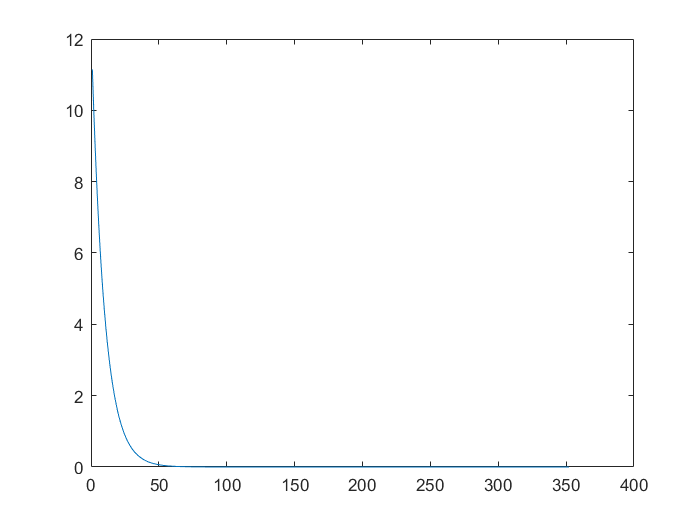

plot(Temp)

## Recocido Usando Toolbox

%Funcion a Optimizar en un formato donde las variables estan en el vector
%x. 
ff = @(x) x(1).^2 + x(2).^2 + 25*((sin(x(1))).^2 + (sin(x(2))).^2);

% Punto inicial de la x
rng('default');
pd=makedist("Uniform",-4,4);
x0=random(pd,1,2);

% Usando el toolbox
x=simulannealbnd(ff,x0)

'simulannealbnd' requires Global Optimization Toolbox.

ff(x)

## Other function

Busquemos el mínimo de la función


$$f(x,y) = (1-x)^2 + 100(y-x^2)^2$$


clear;

% Lets define the function to optimize
f = @(x,y) (1-x).^2 + 100*(y-x.^2).^2;

% Matrices for visualization
[X,Y] = meshgrid(-5:0.1:5,-5:0.1:25);

% Initial guess
rng('shuffle');
aa = -1;
bb = 1;
pd1 = makedist('Uniform',aa,bb);

% Distribution for the new candidate
dx = 0.5;
% pd2 = makedist('Uniform',-dx,dx);
pd2 = makedist('Normal',0,1);
Sol_act = random(pd1,1,2);

% Initial temperature
T0 = 0.5 * f(Sol_act(1),Sol_act(2));
T = T0;  % sets initial temperature

% alpha
alph = 0.85;

% Amount of cicles in the same temperature
ciclesL = 1000;

% Final temperature
Tf = 1E-25;
cc=1;

% This prepares the figure
clf;
hold off
surf(X,Y,f(X,Y))
view([154 45])
% axis equal
alpha 0.75
shading interp
colormap hsv
hold on
while T>Tf
    for ii = 1:ciclesL
        Sol_cand = Sol_act + random(pd2,1,2);
        delta = f(Sol_cand(1),Sol_cand(2)) - ...
                f(Sol_act(1),Sol_act(2));
        
        % Random number and Beltzmon distribution
        x = rand;
        Pboltz = exp(-delta/T);
        
        if x<Pboltz || delta<0
            Sol_act = Sol_cand;
        end
    end
    T = alph * T;
    
    % Visualization
    scatter3(Sol_act(1),Sol_act(2),f(Sol_act(1),Sol_act(2)),100,'.','black'),
%     hold on
    pause(0.01);
%     axis equal;
    cc = cc+1;
end

T
Sol_act
f(Sol_act(1),Sol_act(2))

## Ejercicio

Optimiza la función


$$f(a,b,c,d) = \text{cosh}[(a-1)^2+(b-2)^2+(c+1)^2+(d^2)]$$


## Ejercicio

Optimiza la función


$$f(a,b,c,e,f,g,h) = \text{Re}\left[\frac{a^b + b\:c\:\sin(a^e) - \cos^f\left(\frac{g}{h}\right)}{\sin\left[\left(\frac{a}{f}\right)^h\right]+ \text{tanh}\left(\frac{h}{e\:a}\right)}\right]$$


## Funciones

function nsol = NuevoVecino(sol,dx)
    
    % Distribution for the new candidate
    rng('shuffle')
%     dx = 0.5;
    pd = makedist('Uniform',-dx,dx);
%     pd = makedist('Normal',0,dx);  % Another symmetric distribution :)
    N = length(sol);
    
    % Neighbor
    nsol = sol + random(pd,1,N);
end